# Tuning ottimale controllore PID - joint2

### Caricamento modelli dei processi

clear all; clc; close all

Aggiungo opzione per evitare la molteplicità di 360° nella base.

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

 Carico il modello.

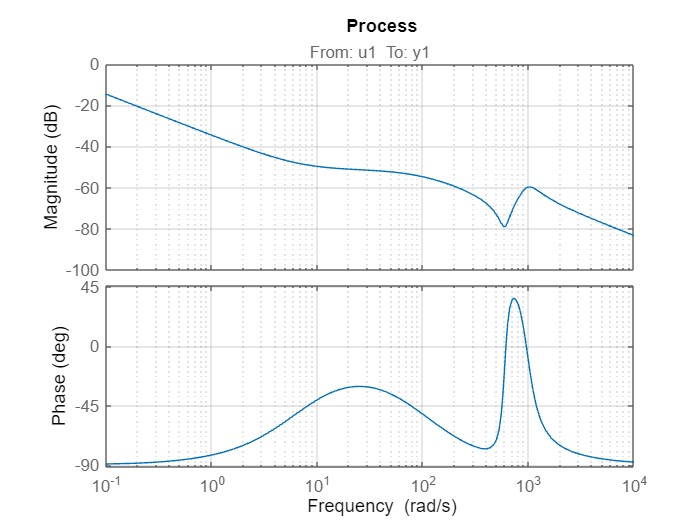

load modello_j2.mat

process = modello_continuo_tf_j2;
figure
bodeplot(process)
grid on; title('Process');

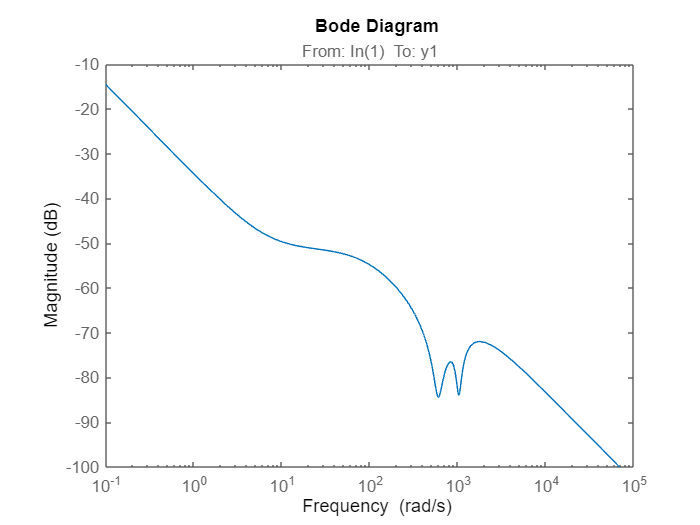

s=tf('s');
w_f=100;
[gpeak,fpeak] = getPeakGain(process*10^(64/20),[],[800 2000]); % constraint of the frequencies personalize for our system
if(gpeak > 1/10)
    notch_filter=notch(fpeak,1/10/gpeak);
else
    notch_filter=1;
end
process_notch = process * notch_filter;
bodemag(process_notch)

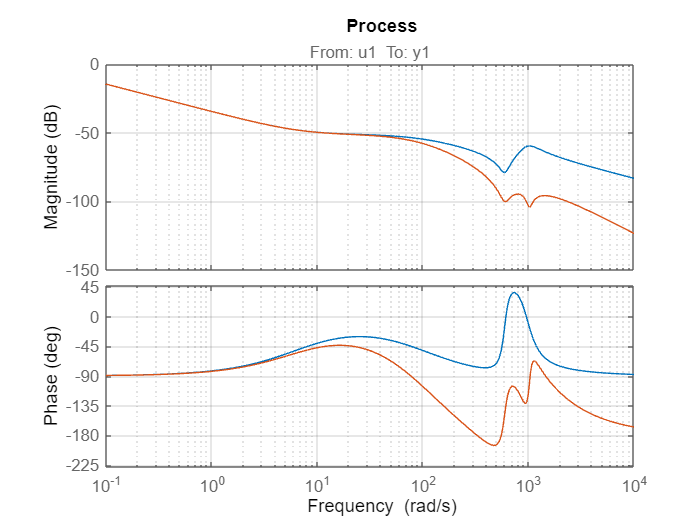

filter = 1/(s/w_f+1)^1;

figure
bode(process,process_notch*filter)
grid on; title('Process');

% ylim([-120 -40])
total_process = minreal(process_notch * filter);

Scelta dell'intervallo di frequenze d'interesse

w_inf = 1;
w_sup = 10^4;

#### Inner loop: output Filtered **P **


$$C_2(s)=K_p \cdot \frac{1}{T_{fu}s+1}$$


Cifra di merito da minimizzare:


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint2.wc_des = 300;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x, 0, 0, 0, 0],total_process,internal_joint2.wc_des,0);

#### Vincoli

- Massima sensitività $MS$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato per $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato per $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Definizione dei vincoli

% Massima sensitività
internal_joint2.MS = 2;

% Reiezione disturbo di misura
internal_joint2.wh = 2000;
internal_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint2.wl = 10;
internal_joint2.Dl_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint2.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare.

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;internal_joint2.wl;internal_joint2.wh]));

Funzione per vincoli non lineari

nlcon = @(x)pid_filt_constraints([x, 0, 0, 0, 0], total_process, w_vector, ...
                                 internal_joint2.MS, internal_joint2.wh, internal_joint2.Fh_max, ...
                                 internal_joint2.wl, internal_joint2.Dl_max, internal_joint2.PM_min,0);

### Ottimizzatore interno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
internal_joint2.aKp = [1400, 100, 10000];
%internal_joint2.aKi = [0, 0, 0];
%internal_joint2.aKd = [0, 0, 0];
%internal_joint2.aTfd = [0, 0, 0];
%internal_joint2.aTfu = [1/300, 1/500, 1/40];

%x0 = [internal_joint2.aKp(1), internal_joint2.aKi(1), internal_joint2.aKd(1), internal_joint2.aTfd(1), internal_joint2.aTfu(1)];
x0 = [internal_joint2.aKp(1)];

% problem = createOptimProblem('fmincon','x0',x0, ...
%                                  'objective',J, ...
%                                  'lb',[internal_joint2.aKp(2), internal_joint2.aKi(2), internal_joint2.aKd(2), internal_joint2.aTfd(2), internal_joint2.aTfu(2)], ...
%                                  'ub',[internal_joint2.aKp(3), internal_joint2.aKi(3), internal_joint2.aKd(3), internal_joint2.aTfd(3), internal_joint2.aTfu(3)], ...
%                                  'nonlcon',nlcon);

problem = createOptimProblem('fmincon','x0',x0,  'objective',J, 'lb',[internal_joint2.aKp(2)],  'ub', [internal_joint2.aKp(3)],  'nonlcon',nlcon);

solver = GlobalSearch('Display','iter','MaxTime',timeout);
x = run(solver,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       18    3.08e+04                                3.08e+04            1    Initial Point
     200     1240    3.08e+04                                3.08e+04            1    Stage 1 Local
     262     3121    3.08e+04     3.714e+04    4.436e+04       0.3885           -1    Stage 2 Local

GlobalSearch stopped because maximum time is exceeded.

GlobalSearch called the local solver 3 times before exceeding 
the clock time limit (MaxTime = 120 seconds).
2 local solver runs converged with a positive local solver exit flag.


x = 1.0249e+03

% solver = MultiStart('Display','iter','MaxTime',timeout,'UseParallel',true);
% addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
% n_startingPoints = 50;
% x = run(solver,problem,n_startingPoints)
nlcon(x)

ans =    -0.0890   -0.0990   -0.4274   -0.0000


s=tf('s');
Kp = x(1);
Cv_joint2 = tf(Kp);
Cv_joint2.InputName = 'sp-vel';
Cv_joint2.OutputName = 'torque';

Loop_int_joint2 = total_process*Cv_joint2;

figure;
subplot(1,2,1)
margin(Loop_int_joint2)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint2))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint2))

ans = 1.5744

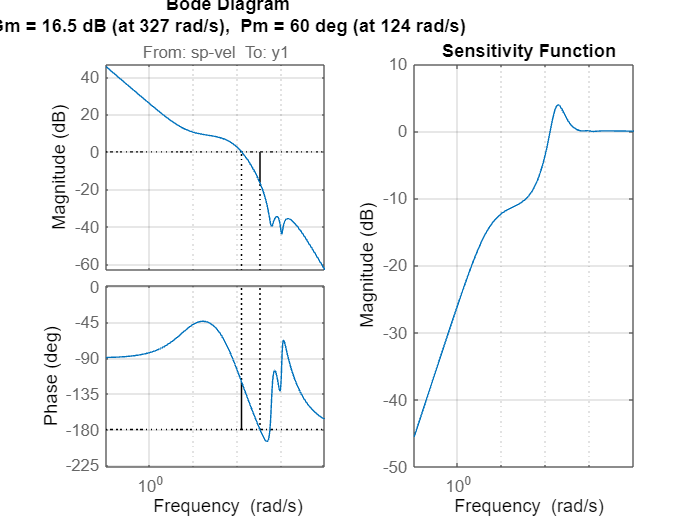

grid on

### Loop esterno: PI

Processo da controllare (velocità → posizione) visto dal controllore esterno: serie tra la funzione di anello chiuso del loop interno e l'integratore (necessario per passare da velocità a posizione).


$$P_{\textrm{ext}} =\frac{C_v \cdot P}{1+C_v \cdot P}\cdot \frac{1}{s}$$


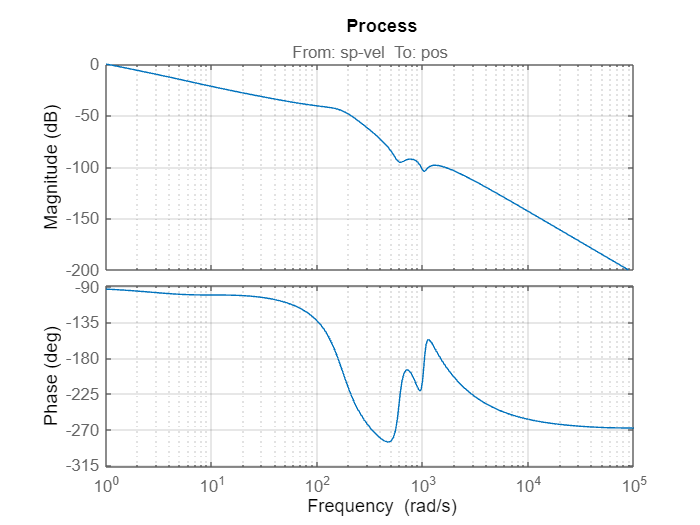

process_ext = minreal(feedback(Loop_int_joint2,1)*1/s);
process_ext.InputName = 'sp-vel';
process_ext.OutputName = 'pos';
figure
bodeplot(process_ext)
grid on; title('Process');

external_joint2.wc_des = 200;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x(1), x(2), 0, 0, 0],process_ext,external_joint2.wc_des,0);

### Vincoli

Definizione dei vincoli

% Massima sensitività
external_joint2.MS = 2;

% Reiezione disturbo di misura
external_joint2.wh = 2000;
external_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint2.wl = 10;
external_joint2.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint2.PM_min = 65;

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;external_joint2.wl;external_joint2.wh]));

nlcon = @(x)pid_filt_constraints([x(1), x(2), 0, 0, 0], process_ext, w_vector, ...
                                 external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
                                 external_joint2.wl, external_joint2.Dl_max, external_joint2.PM_min,0);

### Ottimizzatore esterno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
external_joint2.aKp = [120, 0.01, 2000];
external_joint2.aKi = [1/200, 1/1000, 100];
%external_joint2.aKd = [0, 0, 0];
%external_joint2.aTfd = [0, 0, 0];
%external_joint2.aTfu = [0, 0, 0];

%x0 = [external_joint2.aKp(1), external_joint2.aKi(1), external_joint2.aKd(1), external_joint2.aTfd(1), external_joint2.aTfu(1)];

x0 = [external_joint2.aKp(1), external_joint2.aKi(1)];

% problem = createOptimProblem('fmincon','x0',x0, ...
%                                  'objective',J, ...
%                                  'lb',[external_joint2.aKp(2), external_joint2.aKi(2), external_joint2.aKd(2), external_joint2.aTfd(2), external_joint2.aTfu(2)], ...
%                                  'ub',[external_joint2.aKp(3), external_joint2.aKi(3), external_joint2.aKd(3), external_joint2.aTfd(3), external_joint2.aTfu(3)], ...
%                                  'nonlcon',nlcon);

%solver = GlobalSearch('Display','iter','MaxTime',timeout);
%x = run(solver,problem)
opt1=optimoptions("ga","MaxTime",3600*0.1,'InitialPopulation',x0,'Display','iter');
% x1=ga(J,5,[],[],[],[],[external_joint2.aKp(2), external_joint2.aKi(2), external_joint2.aKd(2), external_joint2.aTfd(2), external_joint2.aTfu(2)] ...
%     ,[external_joint2.aKp(3), external_joint2.aKi(3), external_joint2.aKd(3), external_joint2.aTfd(3), external_joint2.aTfu(3)] ...
%     ,nlcon,opt1);
x1=ga(J,2,[],[],[],[],[external_joint2.aKp(2), external_joint2.aKi(2)] ...
    ,[external_joint2.aKp(3), external_joint2.aKi(3)] ...
    ,nlcon,opt1);


Single objective optimization:
2 Variable(s)
4 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2528       18504.4    0.0001435      0
    2           4990       18504.1    0.0006082      0
    3           7452       18504.5    1.579e-07      0
Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.



% solver = MultiStart('Display','iter','MaxTime',timeout,'UseParallel',true);
% addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
% n_startingPoints = 50;
% x = run(solver,problem,n_startingPoints)

nlcon(x1)

ans =    -0.0996   -0.0869   -0.0467    0.0000


s=tf('s');
Kp=x1(1); Ki=x1(2);
Cp_joint2=(Kp+Ki/s);
Cp_joint2.InputName = 'sp-vel';
Cp_joint2.OutputName = 'pos';

Loop_int_joint2 = process_ext*Cp_joint2;

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
figure;
subplot(1,2,1)
margin(Loop_int_joint2)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint2))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint2))

ans = 2.0881

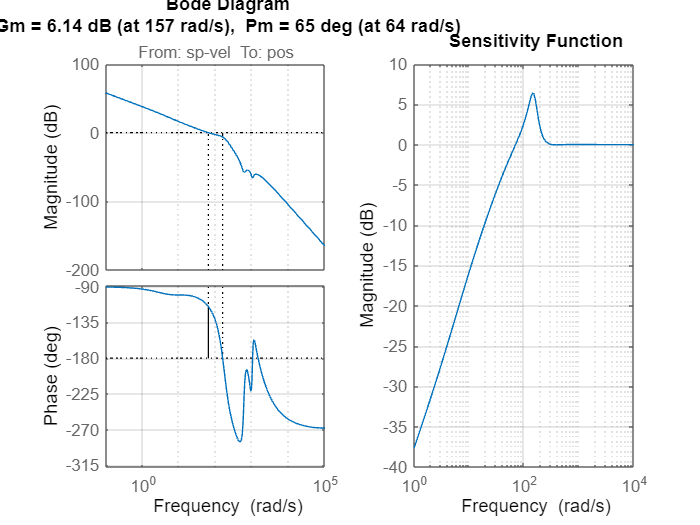

grid on

%x = [x, 0, 0, 0, 0];
%x1 = [x1, 0, 0, 0];
save("parameters_controller_int_joint2_" +num2str(w_f)+".mat", "x")
save("parameters_controller_ext_joint2_"+num2str(w_f)+".mat","x1")